## Brightness Transformation

Functions of brightness transforming

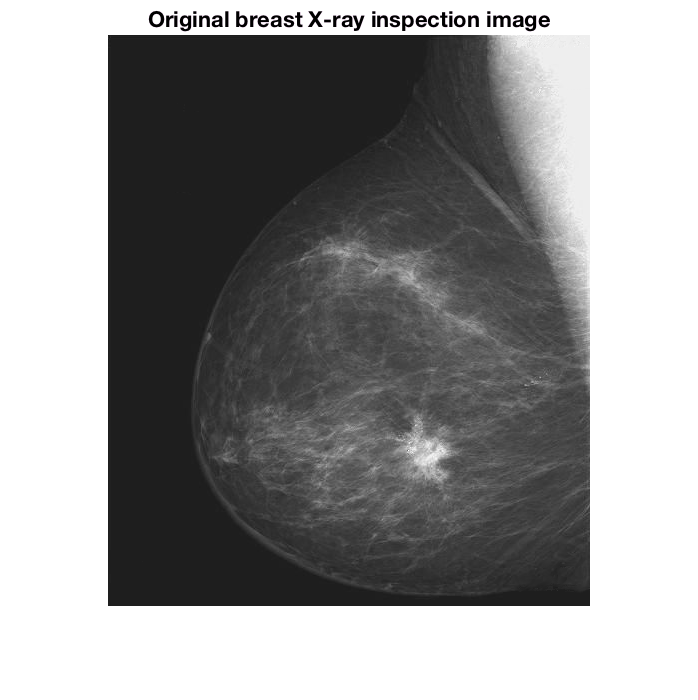

clear
clf
clc

breastImg = imread('Breast_Digital_Xray.tif');
imshow(breastImg);
title('Original breast X-ray inspection image');

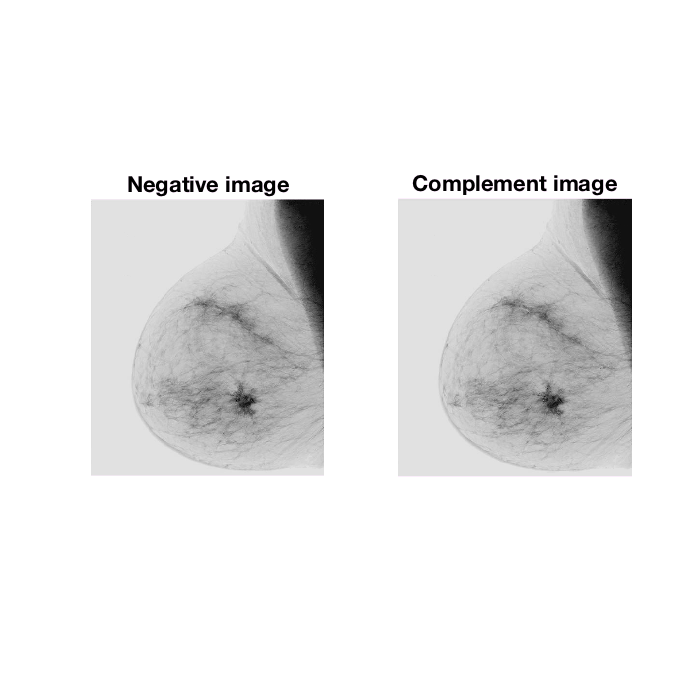

negativeImg = imadjust(breastImg, [0, 1], [1, 0]);
subplot(1, 2, 1), imshow(negativeImg);
title('Negative image');

complementImg = imcomplement(breastImg);
subplot(1, 2, 2), imshow(complementImg);
title('Complement image');

Expand the scope of gray level :

clf;
expandGrayImg = imadjust(breastImg, [0.5, 0.75], [0, 1]);
subplot(2, 1, 1), imshow(expandGrayImg);
title('Image expanded the gray scale');

Adjust the gamma of image : 

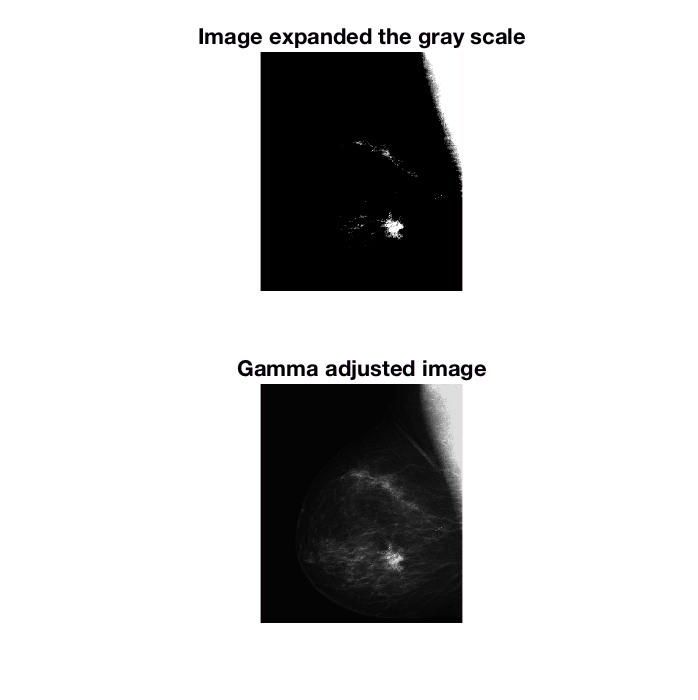

gammaImg = imadjust(breastImg, [], [], 2);
subplot(2, 1, 2), imshow(gammaImg);
title('Gamma adjusted image');

Log transformation image :

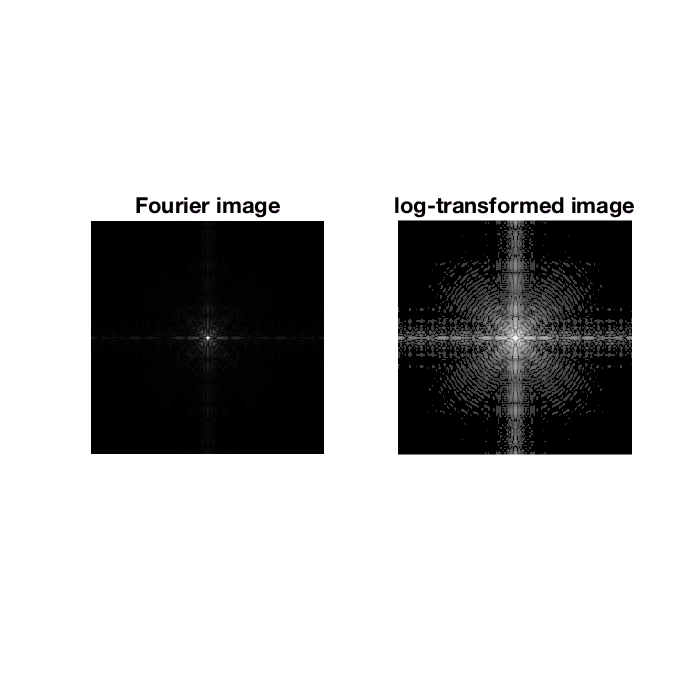

clear
clf

fourierImg = imread('DFT_no_log.tif');
subplot(1, 2, 1), imshow(fourierImg);
title('Fourier image');

logImg = im2uint8(mat2gray(log(1 + double(fourierImg))));
subplot(1, 2, 2), imshow(logImg);
title('log-transformed image');

## Image transformation and enhancement effects:

- stretch 

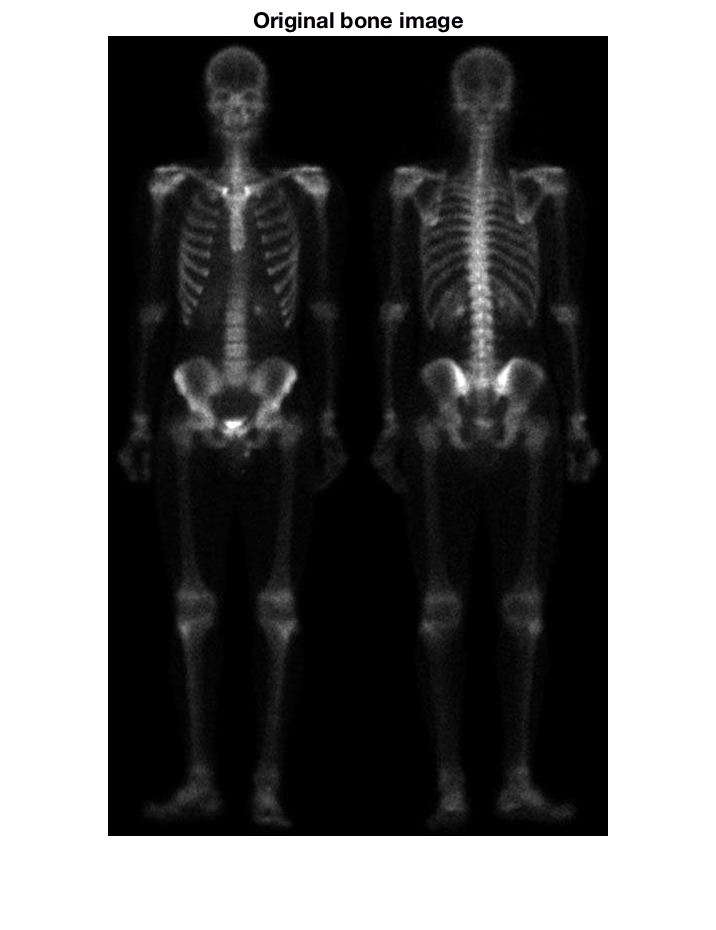

boneImg = imread('bone_scan.tif');
figure, imshow(boneImg);
title('Original bone image');

stretchBoneImg = imtrans(boneImg, 'stretch', mean2(im2double(boneImg)), 0.9);

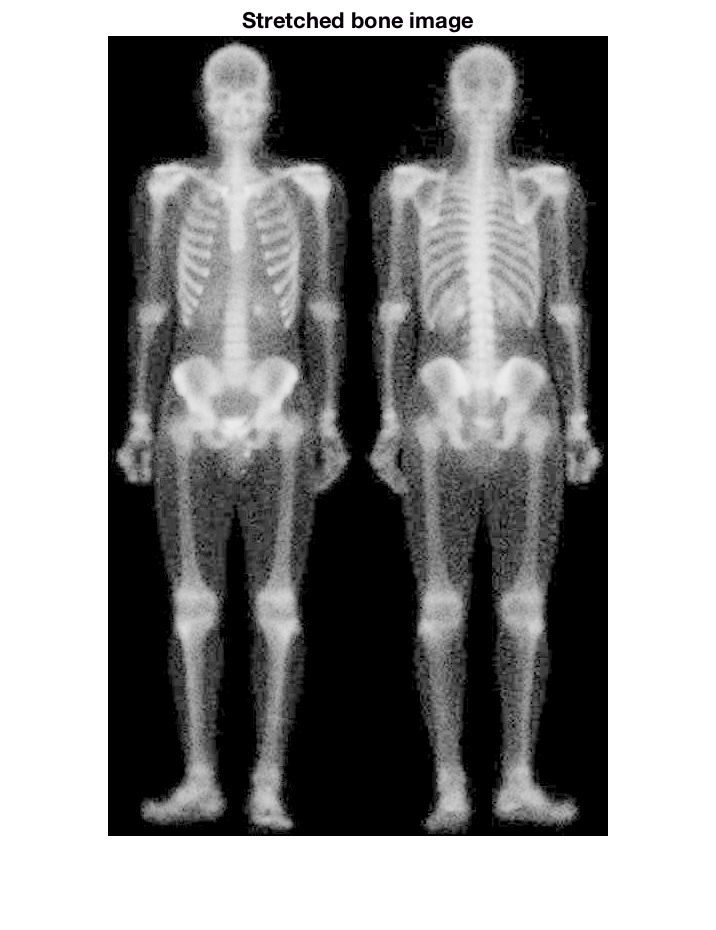

figure, imshow(stretchBoneImg);
title('Stretched bone image');

- gamma

- negative

- log